**1 Comparison Bode Plots of Model Simulink Simulation DC-DC Buck Converter with Model Simulink Simulation Type III Compensator Controller**

clc; 
clear all; 
close all;

%Identify Transfer Function Variable
s = tf('s');

% Assign Estimated Transfer Function From Buck Model Simulink Simulation
REALBUCKTF = load("BuckModelTransferFunction.mat").ans

REALBUCKTF =
 
     2461 s^3 + 3.464e08 s^2 + 4.909e11 s + 1.083e16
  -----------------------------------------------------
  s^4 + 2642 s^3 + 6.172e07 s^2 + 8.008e10 s + 8.848e14
 
Continuous-time transfer function.
Model Properties



% Buck Converter Model Simulink Simulation Values for Reference
%Vin = 12;       % Input Voltage value (V)
%Vout = 5;       % Output Voltage value (V)
%R = 10;         % Load resistance (Ohm)
%L = 350e-6;     % Inductor value (H)
%C = 100e-6;     % Capacitor value (F)
%RL = 0.050;     % Inductor resistance (Ohm)
%RC = 0.025;     % Capacitor resistance (Ohm)
%D = 0.4569;     % Duty Cycle Constant
%PWM = 250e3;    % PWM Generator Switching Frequency (Hz)

% Assign Estimated Transfer Function From Comp Model Simulink Simulation
COMPLETECOMP= load("TypeThreeCompensatorController.mat").ans

COMPLETECOMP =
 
  -8.892e06 s^3 - 1.385e11 s^2 + 1.459e15 s + 1.594e19
  ----------------------------------------------------
     s^4 + 8.499e05 s^3 + 1.909e11 s^2 - 3.226e15 s
 
Continuous-time transfer function.
Model Properties


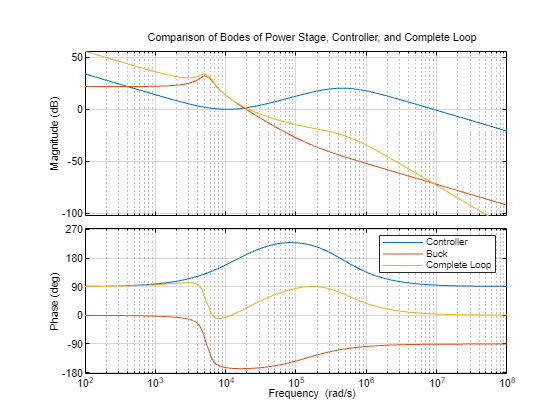


% Type III Compensator Controller Model Simulink Simulation Values for Reference
%Vref= 1.2;                   % Reference Voltage value (V)
%Vout = 5;                    % Output Voltage value (V)
%Rf1 = 20e3;                  % Resistor Rf1 value (Ohm)
%Rc1 = 12.4e3;                % Resistor Rc2 value (Ohm)
%Rf3 = 568;                   % Resistor Rf3 value (Ohm)
%Cc2 = 200e-12;               % Capacitor Cc2 value (F)
%Cc1 = 10.2e-9;               % Capacitor Cc1 value (F)
%Cf3 = 3.7e-9;                % Capacitor Cf3 value (F) (Control this to make phase shift up and down)
%Rf2= 6315.8;                 % Voltage Divider Resistor Rf2 value (Ohm)

% Comparison Bode Plot Displayed
figure()
options = bodeoptions;
options.FreqUnits = 'rad/s';
bode(COMPLETECOMP, options); hold on;
bode(REALBUCKTF,options); hold on;
bode(REALBUCKTF*COMPLETECOMP,options);
grid on
legend('Controller', 'Buck', 'Complete Loop')
title('Comparison of Bodes of Power Stage, Controller, and Complete Loop')

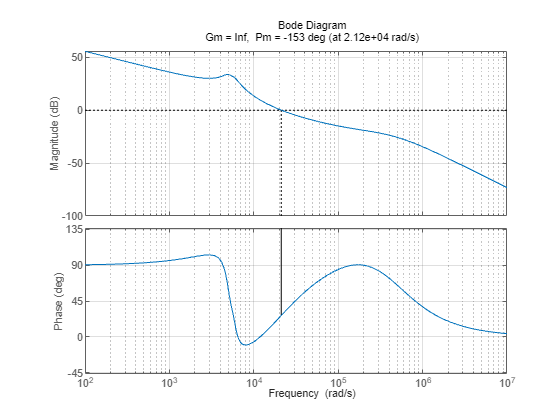


% Margin Bode Plot Displayed
figure()
margin(COMPLETECOMP*REALBUCKTF, options)
grid on